 Machine learning  model to predict flat price in Delhi 

Predictors and targets 

- Area  of flat (in square feet)

 - BHK  (1,2,3,4) 

- Bathroom (1,2,3,4) 

- Furnishing  (Furnished, semi furnished, unfurnished)

 - Locality  

- Parking (1 or 0) 

- Status (Ready to move or almost ready)

 - Transaction (New property or resale) 

- Type (Builder floor or appartment) 

 - Price (1000000 to 240000000 lakh) Target Link to download data:- [https://www.kaggle.com/jatin31/house-...](https://www.youtube.com/redirect?event=video_description&redir_token=QUFFLUhqblR2WTJJVnMzVHJ1amlZNkdhZ1RqTWtjT2prd3xBQ3Jtc0tuenFzNE1rUkpleWc0WkdWNThZeUQxWnlhY0hQX0ExTVNtbVI0Rzc3V2kwQ0pFWTNTeF81ZUhlZFAweU9qa3E2YXpnTW5wSUtYT2xfdkhDVVNDSlltdHM4OW1pS1ZBQnRyY3A5R2NsVmpQVXE1a29nWQ&q=https%3A%2F%2Fwww.kaggle.com%2Fjatin31%2Fhouse-price-prediction-delhi-magicbricks%2Fversion%2F1) 

**Read Data from file**

data=readtable('C:\Users\ammar\Downloads\Compressed\archive\MagicBricks.csv');
data(1:5,:)

ans = 5×13 table
    Area    BHK    Bathroom     Furnishing         Location           District                                     Locality                                Parking         Status            Transaction             Type            Price      Per_Sqft
    ____    ___    ________    _____________    ______________    _________________    ________________________________________________________________    _______    _________________    ________________    _________________    ________    ________

     950     2        2        {'Furnished

**Remove missing Rows**

data=rmmissing(data,1)

data = 961×13 table
    Area    BHK    Bathroom     Furnishing           Location             District                                     Locality                                Parking         Status            Transaction             Type            Price       Per_Sqft 
    ____    ___    ________    _____________    __________________    _________________    ________________________________________________________________    _______    _________________    ________________    _________________    ________    __________

     950     2        2    

sum(sum(ismissing(data)))

ans = 0

**Converte dicerete data in catagorial**

Data=convertvars(data(:,1:end-1),2:9,"categorical")

Data = 961×12 table
    Area    BHK    Bathroom    Furnishing       Location         District                                 Locality                              Parking       Status          Transaction             Type            Price  
    ____    ___    ________    __________    ______________    _____________    ____________________________________________________________    _______    _____________    ________________    _________________    ________

     950     2        2        Furnished     Karol Bagh        Central Delhi    DDA MIG Flats Prasad Nagar Phase 2, Prasad Naga

**Split data in training and testing**

idx=.8*(size(Data,1))

idx = 768.8000

TrainData=Data(1:idx,:);
TestData=Data(768+1:end,:);


**Fit a Gaussian Process Regression (GPR) Mode**

[trainedModel, validationRMSE] = trainRegressionModel(TrainData );

**Compared Predicted Price and Observed Price**

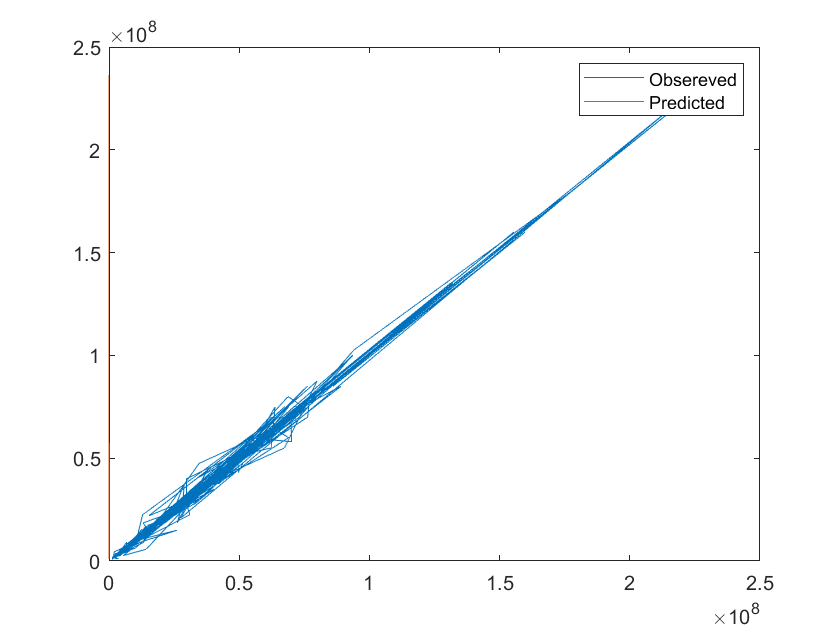

Tpred=trainedModel.predictFcn(TrainData);
plot(Tpred,TrainData.Price)
hold on
plot(Tpred)
hold off
legend('Obsereved','Predicted')

**Test Data** 

Predict prices on testing data

predVal=trainedModel.predictFcn(TestData);

**Compare predicted price vs actual prices**

Remember some data are not trained from test dataset so remove that values.

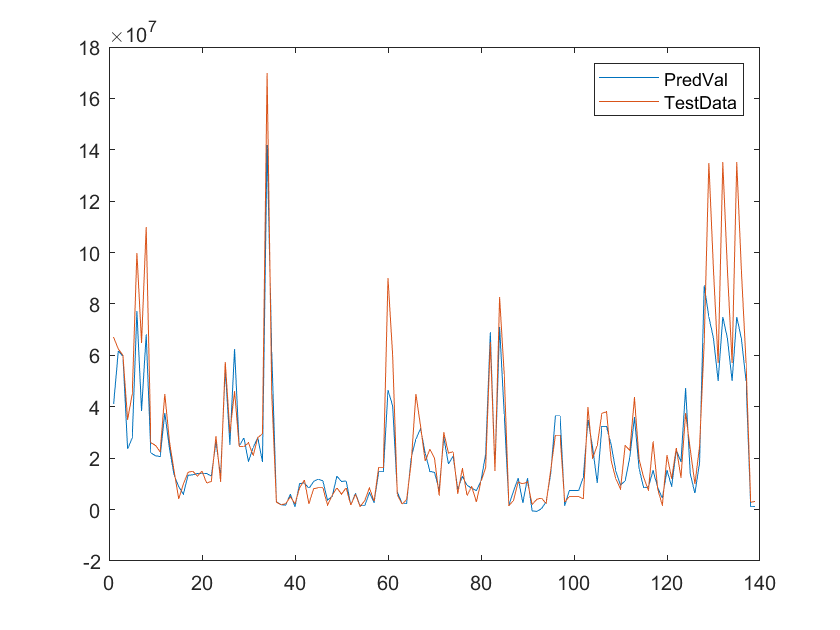

plot(rmmissing (predVal))
hold on 
plot(TestData.Price(~ismissing(predVal)))
hold off
legend('PredVal','TestData')

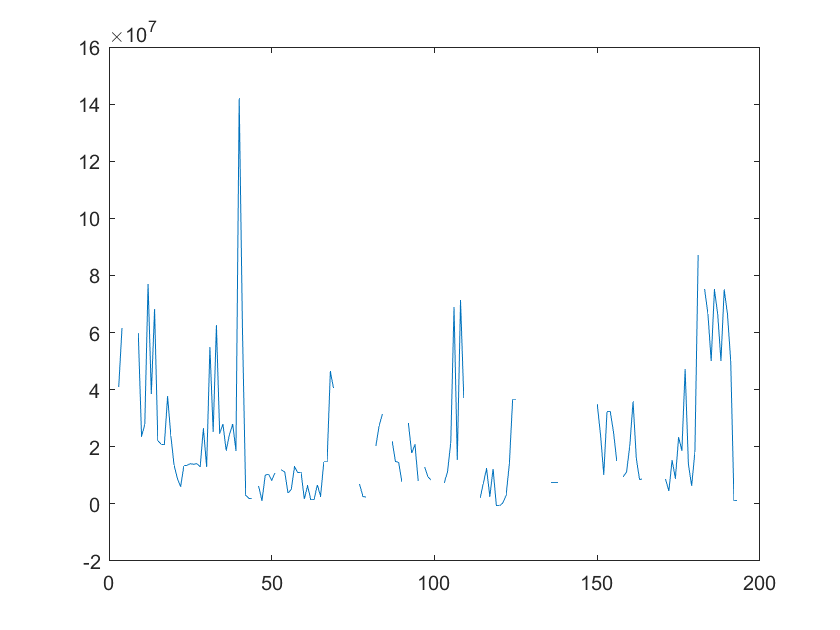

plot(predVal)

function [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% Returns a trained regression model and its RMSE. This code recreates the
% model trained in Regression Learner app. Use the generated code to
% automate training the same model with new data, or to learn how to
% programmatically train models.
%
%  Input:
%      trainingData: A table containing the same predictor and response
%       columns as those imported into the app.
%
%  Output:
%      trainedModel: A struct containing the trained regression model. The
%       struct contains various fields with information about the trained
%       model.
%
%      trainedModel.predictFcn: A function to make predictions on new data.
%
%      validationRMSE: A double containing the RMSE. In the app, the
%       History list displays the RMSE for each model.
%
% Use the code to train the model with new data. To retrain your model,
% call the function from the command line with your original data or new
% data as the input argument trainingData.
%
% For example, to retrain a regression model trained with the original data
% set T, enter:
%   [trainedModel, validationRMSE] = trainRegressionModel(T)
%
% To make predictions with the returned 'trainedModel' on new data T2, usem
% 
%   yfit = trainedModel.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedModel.HowToPredict
 
% Auto-generated by MATLAB on 09-May-2022 10:56:36


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Area', 'BHK', 'Bathroom', 'Furnishing', 'Location', 'District', 'Locality', 'Parking', 'Status', 'Transaction', 'Type'};
predictors = inputTable(:, predictorNames);
response = inputTable.Price;
isCategoricalPredictor = [false, true, true, true, true, true, true, true, true, true, true];

% Train a regression model
% This code specifies all the model options and trains the model.
regressionGP = fitrgp(...
    predictors, ...
    response, ...
    'BasisFunction', 'constant', ...
    'KernelFunction', 'rationalquadratic', ...
    'Standardize', true);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
gpPredictFcn = @(x) predict(regressionGP, x);
trainedModel.predictFcn = @(x) gpPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedModel.RequiredVariables = {'Area', 'BHK', 'Bathroom', 'District', 'Furnishing', 'Locality', 'Location', 'Parking', 'Status', 'Transaction', 'Type'};
trainedModel.RegressionGP = regressionGP;
trainedModel.About = 'This struct is a trained model exported from Regression Learner R2021a.';
trainedModel.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Area', 'BHK', 'Bathroom', 'Furnishing', 'Location', 'District', 'Locality', 'Parking', 'Status', 'Transaction', 'Type'};
predictors = inputTable(:, predictorNames);
response = inputTable.Price;
isCategoricalPredictor = [false, true, true, true, true, true, true, true, true, true, true];

% Set up holdout validation
cvp = cvpartition(size(response, 1), 'Holdout', 0.25);
trainingPredictors = predictors(cvp.training, :);
trainingResponse = response(cvp.training, :);
trainingIsCategoricalPredictor = isCategoricalPredictor;

% Train a regression model
% This code specifies all the model options and trains the model.
regressionGP = fitrgp(...
    trainingPredictors, ...
    trainingResponse, ...
    'BasisFunction', 'constant', ...
    'KernelFunction', 'rationalquadratic', ...
    'Standardize', true);

% Create the result struct with predict function
gpPredictFcn = @(x) predict(regressionGP, x);
validationPredictFcn = @(x) gpPredictFcn(x);

% Add additional fields to the result struct


% Compute validation predictions
validationPredictors = predictors(cvp.test, :);
validationResponse = response(cvp.test, :);
validationPredictions = validationPredictFcn(validationPredictors);

% Compute validation RMSE
isNotMissing = ~isnan(validationPredictions) & ~isnan(validationResponse);
validationRMSE = sqrt(nansum(( validationPredictions - validationResponse ).^2) / numel(validationResponse(isNotMissing) ));
end